% ==========================================================
% fMRI Data Exploration Script with Enhanced Visualizations
% ==========================================================

% Define the directory containing the fMRI files
fmri_dir = 'C:\\Users\\Varadh\\Desktop\\Projects\\fMRI-MATLAB\\fMRI';

% Load a few .nii files for demonstration purposes
subject_id = '414229'; % Specify the subject ID
files = dir(fullfile(fmri_dir, ['wsfREG_rc_', subject_id, '_*.nii']));

% Limit the number of files to process to avoid excessive computation
files = files(1:min(3, length(files))); % Load up to 3 files


% ==========================================================
% Step 1: Load the first fMRI file and extract metadata
% ==========================================================

% Load the first fMRI file to extract metadata and voxel intensity data
file_path = fullfile(fmri_dir, files(1).name);
nii = spm_vol(file_path); % Load header information
img = spm_read_vols(nii); % Load the voxel intensity data
vol_size = size(img);  % Get the spatial dimensions (X, Y, Z)

% Extract voxel size information (real-world spatial resolution in mm)
voxel_size = nii(1).mat(1:3, 1:3); % Extract voxel scaling factors
disp('Voxel Size (mm):');

Voxel Size (mm):


disp(abs(diag(voxel_size)));  % Display voxel size as absolute values

     3
     3
     3



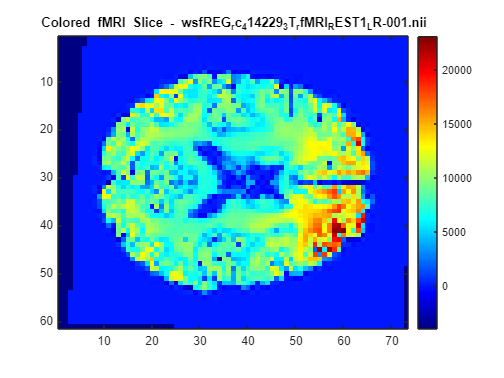


% ==========================================================
% Step 2: Colored Visualization of Brain Slices
% ==========================================================

% Choose the middle axial slice for visualization
mid_slice = round(vol_size(3) / 2);

% Display the fMRI slice with a color-coded colormap
figure;
imagesc(img(:,:,mid_slice)); % Display the middle slice
colormap jet; % Apply a heatmap-like color scheme
axis image;
colorbar;
title(['Colored fMRI Slice - ', files(1).name]);

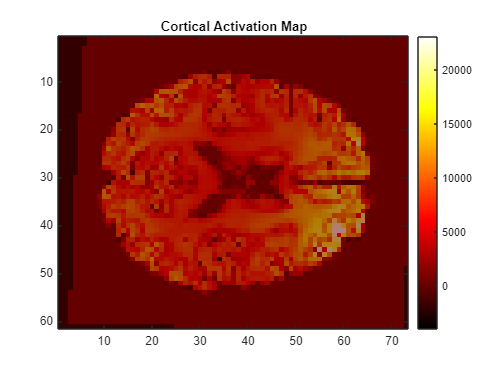


% ==========================================================
% Step 3: Cortical Activation Map
% ==========================================================

% Compute the activation threshold as the top 10% voxel intensities
activation_threshold = prctile(img(:), 90);

% Generate a binary mask highlighting active brain regions
activation_mask = img(:,:,mid_slice) > activation_threshold;

% Display fMRI slice with activation overlay
figure;
imagesc(img(:,:,mid_slice)); % Base grayscale fMRI slice
colormap gray;
hold on;

% Overlay activation regions in red
h = imagesc(activation_mask);
colormap hot;
set(h, 'AlphaData', 0.5); % Adjust transparency for overlay
hold off;

colorbar;
title('Cortical Activation Map');
axis image;

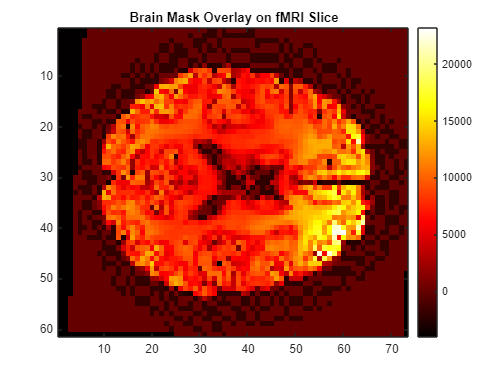


% ==========================================================
% Step 4: Overlay Brain Mask on fMRI Slice
% ==========================================================

% Apply a brain mask to remove non-brain regions from visualization
overlay = img(:,:,mid_slice);
overlay(~brain_mask(:,:,mid_slice)) = NaN; % Mask out non-brain regions

% Display the masked fMRI slice
figure;
imagesc(img(:,:,mid_slice)); % Display the base grayscale slice
colormap gray; % Maintain the original grayscale contrast
hold on;
h = imagesc(overlay); % Overlay the brain mask
colormap hot; % Use a "hot" colormap for the mask
set(h, 'AlphaData', 0.5); % Set transparency for better visualization
hold off;
colorbar;
title('Brain Mask Overlay on fMRI Slice');


% ==========================================================
% Step 5: Comparing Activation in Different Brain Regions
% ==========================================================
% This step selects specific brain regions and compares 
% their activation levels to analyze functional differences.

% Define approximate coordinates for key brain regions
brain_regions = struct( ...
    'PrefrontalCortex', [30, 40, 40], ... 
    'MotorCortex', [35, 35, 30], ... 
    'VisualCortex', [20, 50, 20]); 

% Extract and analyze intensity values for each region
region_stats = struct();
disp('Extracted Intensity Statistics for Key Brain Regions:');

Extracted Intensity Statistics for Key Brain Regions:


PrefrontalCortex - Mean Intensity: 7775.08, Std Dev: 2680.61


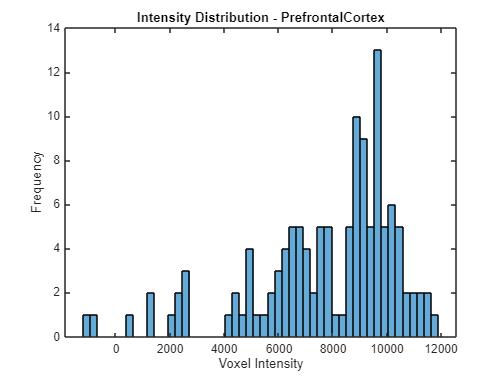

MotorCortex - Mean Intensity: 4240.03, Std Dev: 2948.52


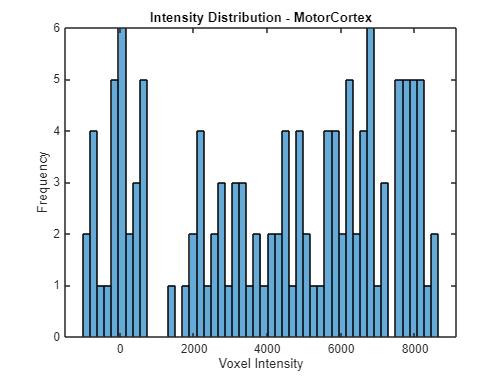

VisualCortex - Mean Intensity: 5302.53, Std Dev: 2852.33


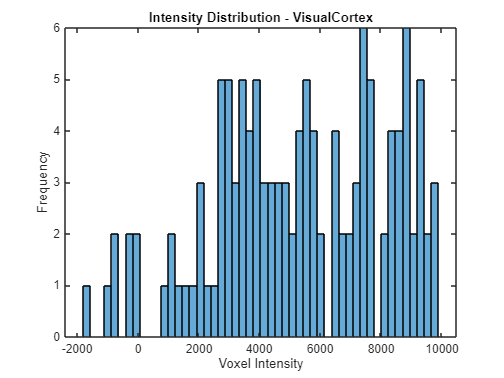

for field = fieldnames(brain_regions)'
    region = field{1};
    coords = brain_regions.(region);
    
    % Extract a small 3D patch around the specified region
    intensity_values = img(coords(1)-2:coords(1)+2, coords(2)-2:coords(2)+2, coords(3)-2:coords(3)+2);
    
    % Compute mean and standard deviation of voxel intensities
    region_stats.(region).Mean = mean(intensity_values(:));
    region_stats.(region).StdDev = std(intensity_values(:));
    
    % Display results in the console
    fprintf('%s - Mean Intensity: %.2f, Std Dev: %.2f\n', ...
        region, region_stats.(region).Mean, region_stats.(region).StdDev);
    
    % Plot histogram for intensity distribution within the region
    figure;
    histogram(intensity_values(:), 50);
    xlabel('Voxel Intensity');
    ylabel('Frequency');
    title(['Intensity Distribution - ', region]);
end


% ==========================================================
% Summary of Exploratory Data Analysis
% ==========================================================
% 1. Extracted voxel intensity variations across slices.
% 2. Identified approx. key brain regions and analyzed their activation levels.
% 3. Visualized fMRI intensity distributions to observe spatial patterns.
% ==========================================================